# Rocky Project Calculations

## Calibration and Setup

### Motor Parameter Estimation

load slower_calibration.m

% Getting the form of the time-domain equation
syms s tau K

M = (K/tau)/(s + (1/tau));
Mt = ilaplace(M)

$$Mt = \frac{K\,{\mathrm{e}}^{-\frac{t}{\tau }}}{\tau }$$

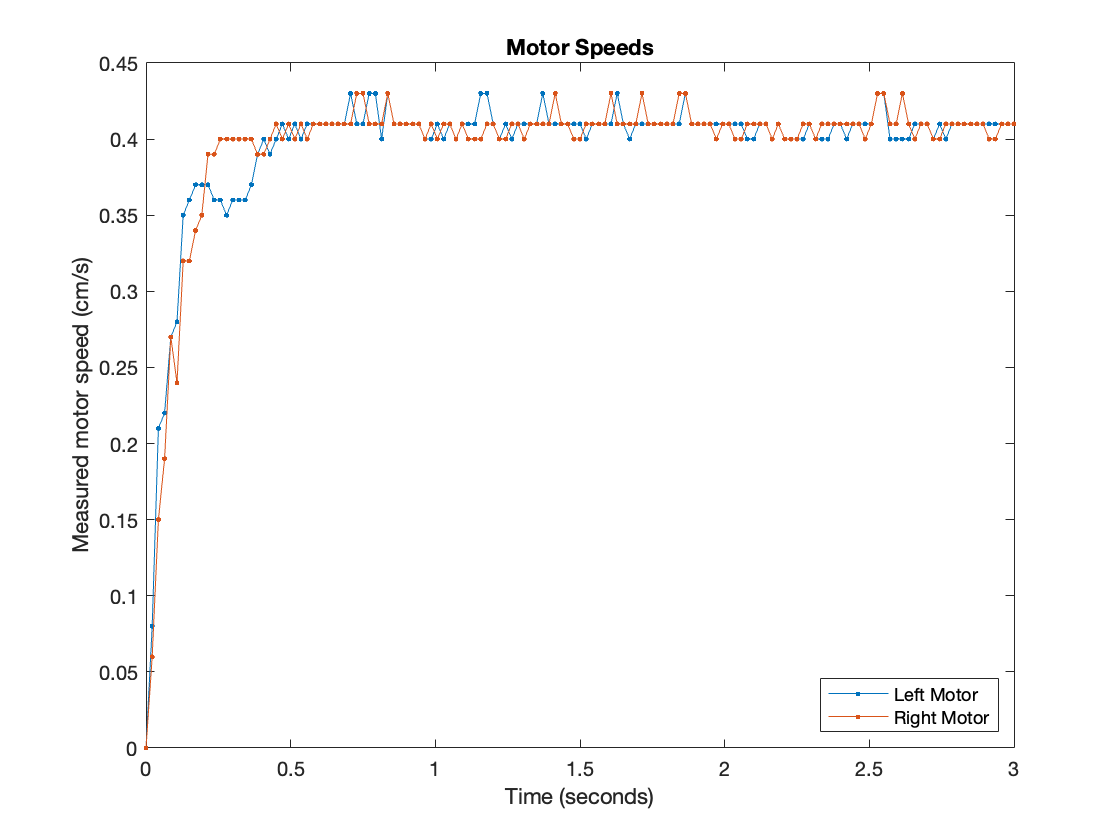


K = -0.05;
tau = 0.08;

% Note: Speeds are measured in cm/s
% Plotting the measured data
figure; clf; 
t = linspace(0, 3, 141);

plot(t, slower_calibration, ".-")

%labelling the plot
title("Motor Speeds")
xlabel("Time (seconds)")
ylabel("Measured motor speed (cm/s)")
legend("Left Motor", "Right Motor", "Location", 'southeast')

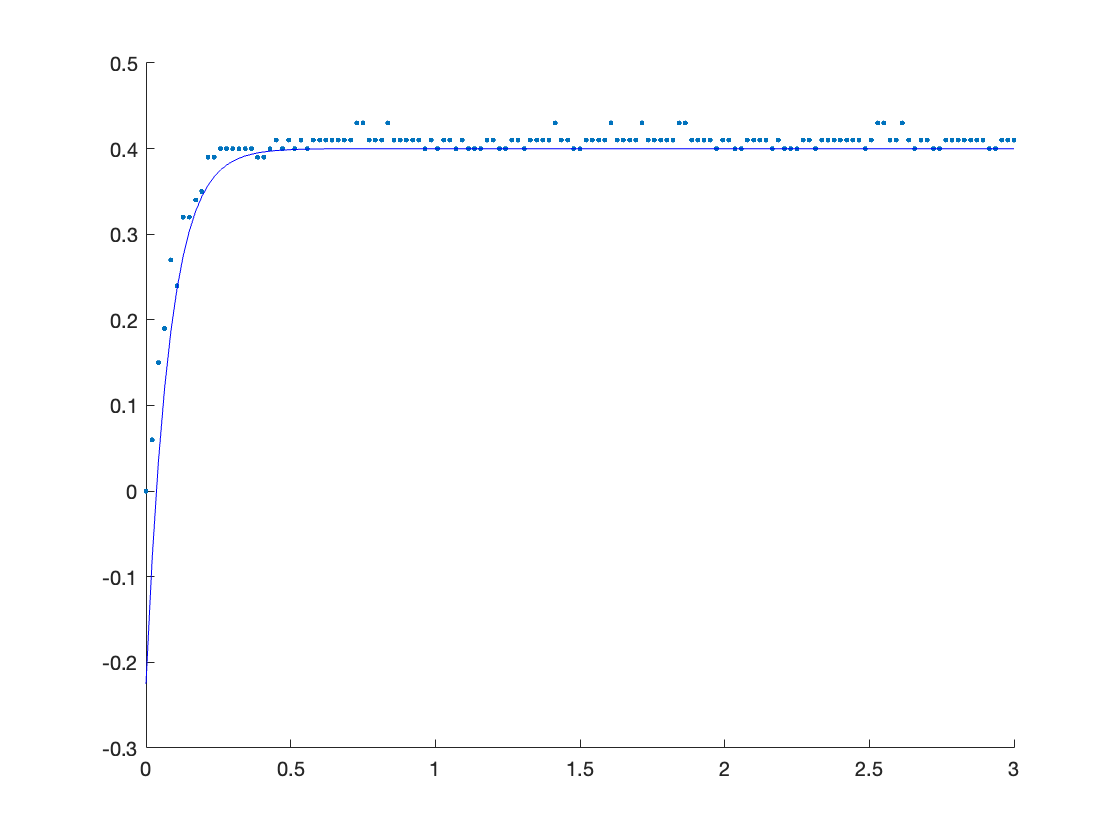


% left motor data a bit jank so we'll do right motor for curve fit
right_s = slower_calibration(:,2);

% plotting right motor data alongside the curve fit
figure; clf; hold on;
plot(t, right_s, ".")
plot(t, (K*exp(-t/tau))/tau + .4, "b-")



% General model Exp2:
%      f(x) = a*exp(b*x) + c*exp(d*x)
% Coefficients (with 95% confidence bounds):
%        a =      0.4106  (0.4067, 0.4146)
%        b =   -0.001392  (-0.006605, 0.003822)
%        c =     -0.4221  (-0.4364, -0.4079)
%        d =      -10.82  (-11.48, -10.17)
% 
% Goodness of fit:
%   SSE: 0.01158
%   R-square: 0.9748
%   Adjusted R-square: 0.9742
%   RMSE: 0.009192


Gyro Calibration

clear
load freq_calibration.m

t = linspace(0, 498*50, 498); %milliseconds
t=t./1000;

figure; clf; hold on;
plot(t(225:400)-t(225), freq_calibration(225:400))

[peaks, locations] = findpeaks(freq_calibration(225:400));
plot(t(locations), peaks, "r.")

title("Rocky's Natural Frequency Calibration Data")
xlabel("Time (seconds)")
ylabel("Displacement (radians)")
legend("Collected data", "Peaks")


diff(t(locations));

ans =     1.3527    1.3026    1.3026    1.3026    1.3026    1.3026



%natural frequency: 4.824 rad/s
